## Model Comparison

### Assignment: Exercise 4-3 (Brunton & Kutz, 2019)

Script author: Emmanuel Rodriguez

[emmanueljrodriguez.com](https://emmanueljrodriguez.com/)

Date: 8DEC2023

Location: Renton, Seattle, WA

clear all;

### Problem Statement

For the temperature data in 'EX4_2_Parabolic_Fit_of_Temp_Data.mlx', consider a polynomial fit of the form:


$$f(x) = \sum^{10}_{k=0} \alpha_k x^k$$


The loadings, $\alpha_k$, are to be determined by four regression techniques:

- Least-squares

- LASSO

- Ridge

- Elastic net

The models are to be compared against each other. 

### Mathematical Background

Curve fitting is an optimization problem, that can be mathematically framed as solving the linear system of equations $Ax=b$.

Recall: $Ax=b$, where $A$ are the model terms, $x$ are the loadings, and $b$ are the outcomes.

#### Import Data

Temperature data taken over a 24-hour cycle is given:

% Temperature data vector
temp = [75, 77, 76, 73, 69, 68, 63, 59, 57, 55, 54, 52,...
    50, 50, 49, 49, 49, 50, 54, 56, 59, 63, 67, 72];

% Time vector
t = 1:24; % ';' suppresses the output

% Query the polynomial fit at n points
n = 100;
tVector=linspace(1,24,n); % Time vector

#### Interpolated Approximation 

Use linear interpolation for the query points

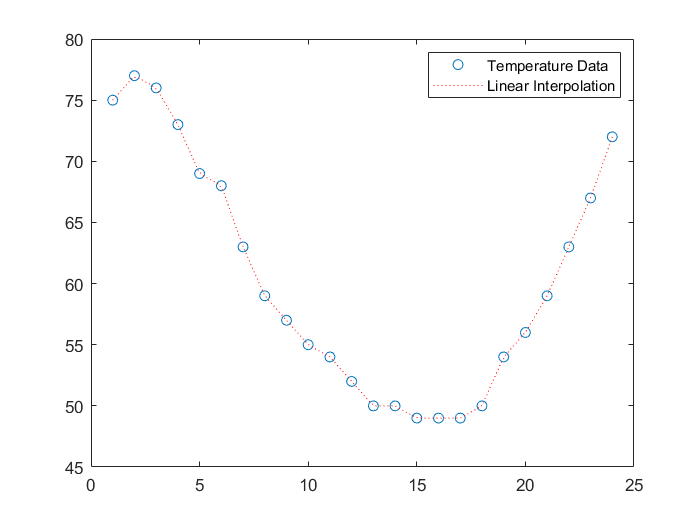

% Linear interpolation
tempInterp = interp1(t,temp,tVector,'linear'); % Interpolated temperature vector
plot(t,temp,'o',tVector,tempInterp,':r');
legend('Temperature Data', 'Linear Interpolation');


% Transpose linear interp
tempInterp = tempInterp';

#### Frame the Model

% Build matrix A
N = 10;  % Polynomial degree, this will be the number of columns
for j = 1:N
    A(:,j) = (tVector.').^(j-1); % ' performs a transpose
end

#### Apply Different Regression Models

lambda = 0.1; % lambda is a parameter used to enforce
% \ell_1-norm penalty, which promotes sparsity.
% I.e., an increase in lambda promotes a sparse solution.
% Sparse meaning that 'statistically insignificant'
% terms are 'dropped' from the loadings set.

A2 = A(:,2:end); % Create a new A-matrix excluding the constant term column, column 1

#### Calculate Loadings and Outputs

Calculate the loadings, $\alpha_k$, or the "weights" (the $x$ column vector) of the different regression models and the corresponding outputs, the $b$ vector.

% Calculate weights

% Calc loadings, or weights; Calc b outputs; Calc error, \ell_2 norm

% Least-squares regression:
x1 = pinv(A)*tempInterp; temp1 = A*x1; E1=norm(tempInterp-temp1)/norm(tempInterp);
% Lasso:
[x2,stats] = lasso(A,tempInterp,'Lambda',lambda); temp2 = A*x2; E2=norm(tempInterp-temp2)/norm(tempInterp);
% Ridge:
x3 = ridge(tempInterp,A2,0.5,0); temp3 = A*x3; E3=norm(tempInterp-temp3)/norm(tempInterp);
% Elastic-net:
[x4,stats] = lasso(A,tempInterp,'Lambda',lambda,'Alpha',0.8); temp4 = A*x4; E4=norm(tempInterp-temp4)/norm(tempInterp);

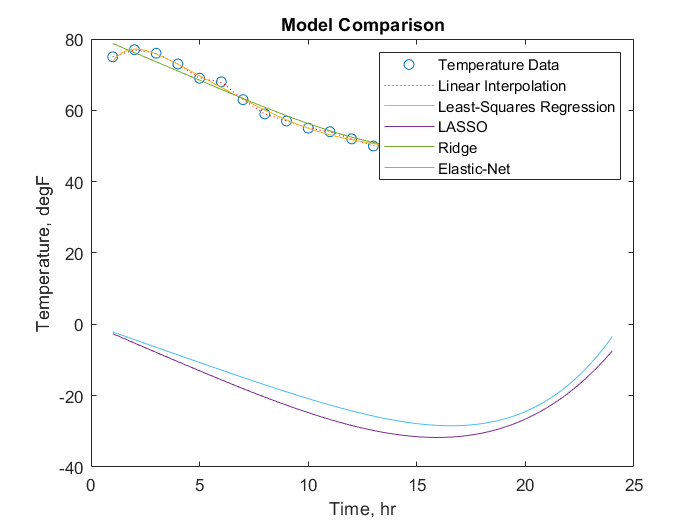

% Plot the results; the temperature prediction from each model
hold on;
plot(tVector,temp1, tVector,temp2, tVector,temp3, tVector,temp4);

legend('Temperature Data', 'Linear Interpolation', 'Least-Squares Regression', 'LASSO', 'Ridge', 'Elastic-Net');
xlabel('Time, hr');
ylabel('Temperature, degF');
title('Model Comparison');

hold off;

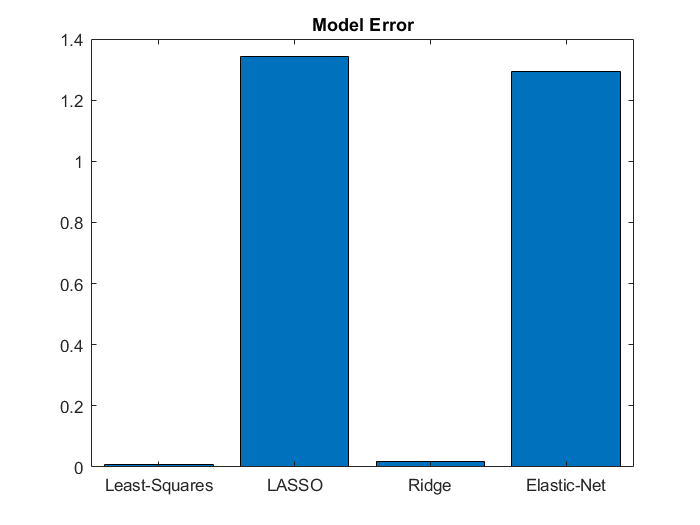


% Plot model error
Err = [E1; E2; E3; E4];
labels = categorical({'Least-Squares','LASSO','Ridge','Elastic-Net'});
labels = reordercats(labels,{'Least-Squares','LASSO','Ridge','Elastic-Net'});
bar(labels,Err);
title('Model Error');

The Model Comparison plot clearly shows LASSO and Elastic-Net to be the "worst" performers, in terms of their poor accuracy in having predictions in close proximity to the actual values, the ground-truth; i.e., the LASSO and Elastic-Net curves are well below the measurements. This is further substantiated by the magnitude of their error seen in the Model Error plot.

The Least-Squares is the best 'fit' and has the smallest error, however, this model may be over-fitting the data. Therefore, Ridge is a **model that is generalizable**, and can be statistically-inferred to yield higher-accuracy results in extrapolation scenarios.

% Apply different regression techniques

for jj=1:100
    % Calc loadings, or weights; Calc b outputs; Calc error, \ell_2 norm
    x1 = pinv(A)*tempInterp; temp1 = A*x1; E1(jj)=norm(tempInterp); % Least-squares regression
    [x2,stats] = lasso(A,tempInterp,'Lambda',lambda); temp2 = A*x2; E2(jj)=norm(tempInterp-temp2)/norm(tempInterp); % Lasso
    x3 = ridge(tempInterp,A2,0.5,0); temp3 = A*x3; E3(jj)=norm(tempInterp-temp3)/norm(tempInterp); % Ridge
    [x4,stats] = lasso(A,tempInterp,'Lambda',lambda,'Alpha',0.8); temp4 = A*x4; E4(jj)=norm(tempInterp-temp4)/norm(tempInterp); % Elastic-net
    X1(:,jj)=x1; X2(:,jj)=x2; X3(:,jj)=x3; X4(:,jj)=x4;
end

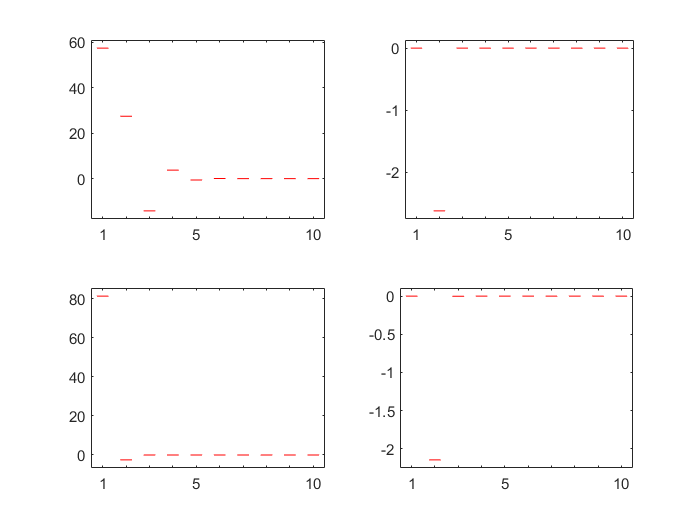

% Plot the value of the loadings?
figure(1)
subplot(2,2,1), boxplot(X1.'), set(gca,'Xtick',1:20,'Xticklabel',{'1','','','','5','','','','','10','','','','','15','','','','','20'})
subplot(2,2,2), boxplot(X2.'), set(gca,'Xtick',1:20,'Xticklabel',{'1','','','','5','','','','','10','','','','','15','','','','','20'})
subplot(2,2,3), boxplot(X3.'), set(gca,'Xtick',1:20,'Xticklabel',{'1','','','','5','','','','','10','','','','','15','','','','','20'})
subplot(2,2,4), boxplot(X4.'), set(gca,'Xtick',1:20,'Xticklabel',{'1','','','','5','','','','','10','','','','','15','','','','','20'})

### References

Brunton, S. L., & Kutz, J. N. (2019). *Data-Driven Science and Engineering.* Cambridge: Cambridge University Press.

Chapra, S. C., & Canale, R. P. (2014). *Numerical Methods for Engineers* (7th ed.). New York: McGraw-Hill Higher Education.